%data_processing_plots
% times table 
% Loose,                     Medium,                  Tight
% 100,200,300,400,500
% Bogacki FG
% Bogacki TT
% Fehlberg FG
% Fehlberg TT
% Verner FG
% Verner TT
% Define file names corresponding to each tolerance level.
close all; clear
addpath('../../../src')

fileNames = {'loose_tol_results.mat', 'medium_tol_results.mat', 'tight_tol_results.mat'};
tollevel = {'loose', 'medium', 'tight'};
Methods  = {'Bogacki-Shampine-ERK','Fehlberg-ERK','Verner-6-5-ERK'};
nTolerances = numel(fileNames);
nVersions = 2;
Versions = {'TT','FG'};

nMethods = 3;
nGrids = 5;
gridPoints = 100:100:500;

% Preallocate containers for runtime and error data.
runtimeData = cell(nTolerances, 1);
errorData   = cell(nTolerances, 1);
stepData  = cell(nTolerances, 1); 
timeperStepData = cell(nTolerances, 1);
failedStepData = cell(nTolerances, 1);

## Get Stored Data

for tol = 1:nTolerances
    % Load the MAT file. 
    L = load(fileNames{tol});  
    data = L.(tollevel{tol});

    % Initialize matrices to store runtime and error for each method/grid.
    runtime = zeros(nMethods, nGrids, nVersions);
    maxrelerror = zeros(nMethods, nGrids, nVersions);
    nsteps = zeros(nMethods, nGrids, nVersions);
    timepstep = zeros(nMethods, nGrids, nVersions);
    nfail = zeros(nMethods, nGrids, nVersions);

       % Loop through the cell array (3 rows = methods, 5 cols = grid points)
    for method = 1:nMethods
        for grid = 1:nGrids
            % Access the struct in the current cell
            s = data{method, grid};
            
            % Extract fields
            runtime(method, grid,1) = s.tt_time;
            maxrelerror(method, grid,1) = max(s.tterror);
            runtime(method, grid,2) = s.fg_time;
            maxrelerror(method,grid,2) = max(s.fgerror);
            nsteps(method, grid, 1) = s.nstepstt; 
            nsteps(method, grid, 2) = s.nstepsfg; 
            nfail(method, grid, 1) = s.nfailtt; 
            nfail(method, grid, 2) = s.nfailfg;
        end
    end
    
    runtimeData{tol} = runtime;
    errorData{tol}   = maxrelerror;
    stepData{tol} = nsteps;
    timeperStepData{tol} = runtime./nsteps;
    failedStepData{tol} = nfail;
end

lineStyles = {'-', '--'};
markers    = {'o', 'x'};


## Try convergence tests in time

% Data is rows is tolerance data and columns is N values 
method1datafg = [errorData{1}(1,:,1); errorData{2}(1,:,1); errorData{3}(1,:,1)];
method1datatt = [errorData{1}(1,:,2); errorData{2}(1,:,2); errorData{3}(1,:,2)];
method2datafg = [errorData{1}(2,:,1); errorData{2}(2,:,1); errorData{3}(2,:,1)];
method2datatt = [errorData{1}(2,:,2); errorData{2}(2,:,2); errorData{3}(2,:,2)];
method3datafg = [errorData{1}(3,:,1); errorData{2}(3,:,1); errorData{3}(3,:,1)];
method3datatt = [errorData{1}(3,:,2); errorData{2}(3,:,2); errorData{3}(3,:,2)];
[ntol,nNx] = size(method1datatt);
rtols = [1e-4;1e-5;1e-6];
atols = [1e-9;1e-10;1e-11];
pfg1 = {}; ptt1 = {};
pfg2 = {}; ptt2 = {};
pfg3 = {}; ptt3 = {};
for i = 1:nNx
    pfg1{end+1} = polyfit(log10(rtols),log10(method1datafg(:,i)),1);
    ptt1{end+1} = polyfit(log10(rtols),log10(method1datatt(:,i)),1);
    pfg2{end+1} = polyfit(log10(rtols),log10(method2datafg(:,i)),1);
    ptt2{end+1} = polyfit(log10(rtols),log10(method2datatt(:,i)),1);
    pfg3{end+1} = polyfit(log10(rtols),log10(method3datafg(:,i)),1);
    ptt3{end+1} = polyfit(log10(rtols),log10(method3datatt(:,i)),1);
end

## Plot Runtimes

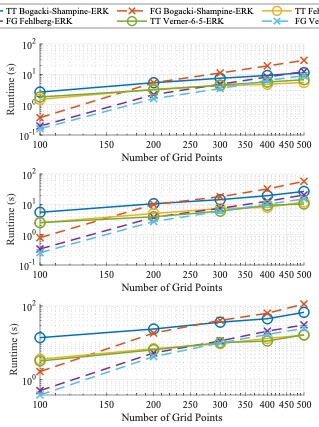

figure('Units', 'normalized', 'Position', [0.01 0.1 0.25 0.8]); % Figure position on screen and size
t = tiledlayout(nTolerances, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
hLegend = [];  % Collect plot handles for legend

for tol = 1:nTolerances
    ax = nexttile;  % Get next tile (subplot)
    hold(ax, 'on');
    for method = 1:nMethods
        for ver = 1:nVersions
            % Plot runtime vs. grid points.
            h = plot(ax, gridPoints, runtimeData{tol}(method, :, ver), ...
                [lineStyles{ver} markers{ver}], 'LineWidth', 1.5);
            % Collect handles only from the first tile for the global legend.
            if tol == 1
                hLegend(end+1) = h;
            end
        end
    end
    hold(ax, 'off');
    xlabel(ax, 'Number of Grid Points');
    ylabel(ax, 'Runtime (s)');
    set(gca,'XScale','log','YScale','log')
end

% Build legend labels (same for all subplots)
legendLabels = {};
for method = 1:nMethods
    for ver = 1:nVersions
        mname = Methods{method};
        vname = Versions{ver};
        legendLabels{end+1} = sprintf('%s %s', vname, mname);
    end
end
lgd = legend(hLegend, legendLabels, 'Orientation', 'horizontal');
lgd.NumColumns = min(3, numel(legendLabels));  % Adjust number of columns if needed
lgd.Layout.Tile = 'north';  % position of legend

## Plot error.

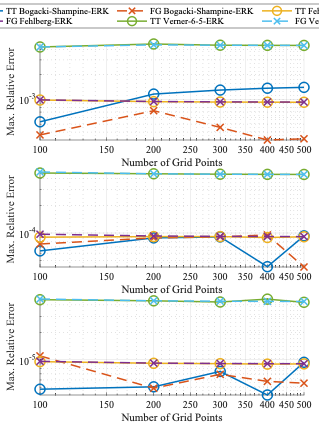

figure('Units', 'normalized', 'Position', [0.01 0.1 0.25 0.8]); % Figure position on screen and size
t = tiledlayout(nTolerances, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
hLegend = [];  % Collect plot handles for legend

for tol = 1:nTolerances
    ax = nexttile;  % Get next tile (subplot)
    hold(ax, 'on');
    for method = 1:nMethods
        for ver = 1:nVersions
            % Plot runtime vs. grid points.
            h = loglog(ax, gridPoints, errorData{tol}(method, :, ver), ...
                [lineStyles{ver} markers{ver}], 'LineWidth', 1.5);
            % Collect handles only from the first tile for the global legend.
            if tol == 1
                hLegend(end+1) = h;
            end
        end
    end
    hold(ax, 'off');
    xlabel(ax, 'Number of Grid Points');
    ylabel(ax, 'Max. Relative Error');
    set(gca,'XScale','log','YScale','log')

end

% Build legend labels (same for all subplots)
legendLabels = {};
for method = 1:nMethods
    for ver = 1:nVersions
        mname = Methods{method};
        vname = Versions{ver};
        legendLabels{end+1} = sprintf('%s %s', vname, mname);
    end
end
lgd = legend(hLegend, legendLabels, 'Orientation', 'horizontal');
lgd.NumColumns = min(3, numel(legendLabels));  % Adjust number of columns if needed
lgd.Layout.Tile = 'north';  % position of legend

## Plot steps.

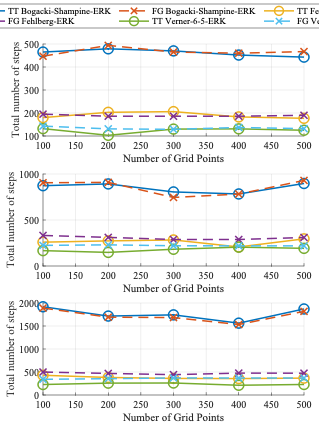

figure('Units', 'normalized', 'Position', [0.01 0.1 0.25 0.8]); % Figure position on screen and size
t = tiledlayout(nTolerances, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
hLegend = [];  % Collect plot handles for legend

for tol = 1:nTolerances
    ax = nexttile;  % Get next tile (subplot)
    hold(ax, 'on');
    for method = 1:nMethods
        for ver = 1:nVersions
            % Plot runtime vs. grid points.
            h = plot(ax, gridPoints, stepData{tol}(method, :, ver), ...
                [lineStyles{ver} markers{ver}], 'LineWidth', 1.5);
            % Collect handles only from the first tile for the global legend.
            if tol == 1
                hLegend(end+1) = h;
            end
        end
    end
    hold(ax, 'off');
    xlabel(ax, 'Number of Grid Points');
    ylabel(ax, 'Total number of steps');
end

% Build legend labels (same for all subplots)
legendLabels = {};
for method = 1:nMethods
    for ver = 1:nVersions
        mname = Methods{method};
        vname = Versions{ver};
        legendLabels{end+1} = sprintf('%s %s', vname, mname);
    end
end
lgd = legend(hLegend, legendLabels, 'Orientation', 'horizontal');
lgd.NumColumns = min(3, numel(legendLabels));  % Adjust number of columns if needed
lgd.Layout.Tile = 'north';  % position of legend

## Plot time per steps

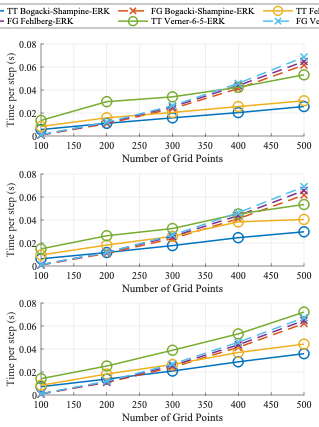

figure('Units', 'normalized', 'Position', [0.01 0.1 0.25 0.8]); % Figure position on screen and size
t = tiledlayout(nTolerances, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
hLegend = [];  % Collect plot handles for legend

for tol = 1:nTolerances
    ax = nexttile;  % Get next tile (subplot)
    hold(ax, 'on');
    for method = 1:nMethods
        for ver = 1:nVersions
            % Plot runtime vs. grid points.
            h = plot(ax, gridPoints, timeperStepData{tol}(method, :, ver), ...
                [lineStyles{ver} markers{ver}], 'LineWidth', 1.5);
            % Collect handles only from the first tile for the global legend.
            if tol == 1
                hLegend(end+1) = h;
            end
        end
    end
    hold(ax, 'off');
    xlabel(ax, 'Number of Grid Points');
    ylabel(ax, 'Time per step (s)');
end

% Build legend labels (same for all subplots)
legendLabels = {};
for method = 1:nMethods
    for ver = 1:nVersions
        mname = Methods{method};
        vname = Versions{ver};
        legendLabels{end+1} = sprintf('%s %s', vname, mname);
    end
end
lgd = legend(hLegend, legendLabels, 'Orientation', 'horizontal');
lgd.NumColumns = min(3, numel(legendLabels));  % Adjust number of columns if needed
lgd.Layout.Tile = 'north';  % position of legend

## Plot bar plots for number of steps and failed steps

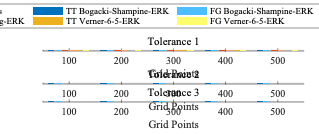

groupWidth = 0.8;  % Fraction of 1 unit dedicated to a grid group
nBars = nMethods * nVersions;         % Total number of bars in a group
barWidth = groupWidth / nBars;        % Width for each bar

% Colors: Use distinct colors for methods (MATLAB's default lines colormap)
methodColors = lines(nMethods);
% Set a fixed color for failed steps that does not conflict with methodColors
cFail = [0.3, 0.3, 0.3];  % a dark gray

figure('Units','normalized','Position',[0.1, 0.1, 0.8, 0.8]);
t = tiledlayout(nTolerances,1, 'TileSpacing','compact','Padding','compact');

% Prepare containers to collect legend handles from the first tolerance & grid group
hFailed = [];         % handle for failed steps patch
hSuccess = cell(nMethods, nVersions);  % handles for each method/version (success part)

for tol = 1:nTolerances
    ax = nexttile;
    hold(ax, 'on');
    
    % Loop over each grid (group)
    for grid = 1:nGrids
        % The center of this grid group is at x = grid.
        % Calculate the left edge so that the group is centered.
        x0 = grid - groupWidth/2;
        
        % For each method and version in order:
        for method = 1:nMethods
            for ver = 1:nVersions
                % Determine x-position of the bar:
                % Bars are ordered so that each method's versions are next to each other.
                xPos = x0 + ((method-1)*nVersions + (ver-1)) * barWidth;
                
                % Get number of stages 
                B = butcher(Methods{method});
                stages = numel(B(1,:))-1;

                % Extract data from the current cell's 3D arrays.
                failVal = failedStepData{tol}(method, grid, ver)*stages;
                stepVal = stepData{tol}(method, grid, ver)*stages;
                
                % Draw the lower rectangle for failed steps.
                rectangle('Position', [xPos, 0, barWidth*0.9, failVal], ...
                          'FaceColor', cFail, 'EdgeColor', 'none');
                % Determine the success (step data) color.
                if ver == 1
                    successColor = methodColors(method,:);
                else
                    % For version 2, lighten the method's color by adding 0.3 (capped at 1).
                    successColor = min(methodColors(method,:) + 0.3, 1);
                end
                
                % Draw the upper rectangle for step data, stacked on top of the failed data.
                rectangle('Position', [xPos, failVal, barWidth*0.9, stepVal - failVal], ...
                          'FaceColor', successColor, 'EdgeColor', 'none');
                
                % Save legend handles only from the first tolerance and first grid group.
                if tol == 1 && grid == 1
                    % Save the handle for this method/version combination.
                    hSuccess{method, ver} = patch(NaN, NaN, successColor, 'EdgeColor', 'none');
                end
            end
        end
        
        % Save the handle for failed steps (only once).
        if tol == 1 && grid == 1 && isempty(hFailed)
            hFailed = patch(NaN, NaN, cFail, 'EdgeColor', 'none');
        end
    end
    
    hold(ax, 'off');
    % Set X-axis ticks so that grid groups appear at integer positions.
    set(ax, 'XTick', 1:nGrids,'XTickLabel', 100:100:500, 'XLim', [0.5, nGrids+0.5]);
    xlabel(ax, 'Grid Points');
    ylabel(ax, 'Steps');
    title(ax, sprintf('Tolerance %d', tol));
end

% The first legend entry is for failed steps.
legendHandles = [hFailed];
legendLabels = {'Failed Steps'};

% Then add one entry per method/version combination.
for method = 1:nMethods
    for ver = 1:nVersions
        mname = Methods{method};
        vname = Versions{ver};
        legendHandles(end+1) = hSuccess{method, ver};
        legendLabels{end+1} = sprintf('%s %s', vname, mname);
    end
end

lgd = legend(legendHandles, legendLabels, 'Orientation','horizontal');
% Force the legend into multiple rows if needed.
lgd.NumColumns = ceil(length(legendLabels)/2);
% Adjust the legend position if necessary.
lgd.Layout.Tile = 'north';  % position of legend

## Create Table

Preallocate cell arrays for table columns.

numRows = nTolerances * nGrids * nMethods * nVersions;
TolCol      = cell(numRows,1);  % Tolerance names from tollevel
GridCol     = cell(numRows,1);  % Grid point values (as strings)
MethCol     = cell(numRows,1);  % Method names from Methods
VerCol      = cell(numRows,1);  % Version names from Versions
TotStepsCol = cell(numRows,1);  % Total steps (formatted as string)
FailPctCol  = cell(numRows,1);  % Failed percentage (formatted as string)

row = 1;
% Loop order: tolerance, then grid, then method, then version.
for tol = 1:nTolerances
    for grid = 1:nGrids
        for method = 1:nMethods
            for ver = 1:nVersions
                % Extract the numeric values.
                totSteps = stepData{tol}(method, grid, ver); 
                failed   = failedStepData{tol}(method, grid, ver);
                
                % Compute percentage (handle totSteps==0 if needed).
                if totSteps > 0
                    pctFailed = 100 * (failed / totSteps);
                else
                    pctFailed = 0;
                end
                
                % Fill the columns:
                TolCol{row}  = tollevel{tol};
                % Convert grid index to a grid point value (e.g., 1->100, 2->200, etc.)
                GridCol{row} = sprintf('%.2f', grid*100);
                MethCol{row} = Methods{method};
                VerCol{row}  = Versions{ver};
                TotStepsCol{row} = sprintf('%.2f', totSteps);
                FailPctCol{row}  = sprintf('%.2f', pctFailed);
                
                row = row + 1;
            end
        end
    end
end

% Create the table with appropriate variable names.
T = table(GridCol, VerCol, MethCol, TolCol, TotStepsCol, FailPctCol, ...
    'VariableNames', {'GridPoint', 'Version', 'Method', 'Tolerance', 'TotalSteps', 'FailedPercentage'});

% Display the table.
disp(T);

    GridPoint     Version             Method             Tolerance     TotalSteps     FailedPercentage
    __________    _______    ________________________    __________    ___________    ________________

    {'100.00'}    {'TT'}     {'Bogacki-Shampine-ERK'}    {'loose' }    {'465.00' }       {'41.72'}    
    {'100.00'}    {'FG'}     {'Bogacki-Shampine-ERK'}    {'loose' }    {'447.00' }       {'41.39'}    
    {'100.00'}    {'TT'}     {'Fehlberg-ERK'        }    {'loose' }    {'180.00' }       {'29.44'}    
    {'100.00'}    {'FG'}     {'Fehlberg-ERK'        }    {'loose' }    {'195.00' }       {'34.87'}    
    {'100.00'}    {'TT'}     {'Verner-6-5-ERK'      }    {'loose' }    {'132.00' }       {'23.48'}    
    {'100.00'}    {'FG'}     {'Verner-6-5-ERK'      }    {'loose' }    {'1